freqpath = 'C:\Users\bgrau\Dropbox (Dartmouth College)\PBS\2023_Graul_EEE\Data\EEE\processed\sub-01\imgview_freq_2b5a';
preproc = 'C:\Users\bgrau\Dropbox (Dartmouth College)\PBS\2023_Graul_EEE\Data\EEE\processed\sub-01\imgview_preproc_2b5a';
erp = 'C:\Users\bgrau\Dropbox (Dartmouth College)\PBS\2023_Graul_EEE\Data\EEE\processed\sub-01\imgview_ERP_2b5a';


load(freqpath);
load(preproc);
load(erp);


It's easiest to have a quick table to reference for the direct high-low cue comparisons within pair. It can be made from the trial info within the FieldTrip objects.

pairs = table();
hiorder = sortrows(imgview_freq.trialinfo, 'highcue_indx', 'descend');
pairorder = sortrows(imgview_freq.trialinfo, 'Pair');
pairs.pairnum = hiorder.Pair(1:32);
pairs.hitrial = hiorder.trial(1:32);
pairs.lotrial = hiorder.pair_row(1:32);
pairs.hival = hiorder.val_rating(1:32);
pairs.loval = hiorder.val_rating(33:64);
pairs.valdif = pairs.hival - pairs.loval;
pairs.hiexp = hiorder.exp_rating(1:32);
pairs.loexp  = hiorder.exp_rating(33:64);
pairs.expdif = pairs.hiexp  - pairs.loexp;
pairs = sortrows(pairs, 'pairnum', 'ascend');


We want to start with looking in the amygdala. The electrode RTA1 is a good candidate for this. It's electrode #47 in our current dataset. If other electrodes are of interest, their number is the row number they appear on within the imgview_freq.label cell array.

%%
imgview_powspctrm_RTA1 = squeeze(imgview_freq.powspctrm(:,47,:,:));
xc = imgview_powspctrm_RTA1;

ii = 1;
difftable = [];

for r = 1:2:64
    if pairorder.highcue_indx(r) == 1
        j = pairorder.trial(r);
        k = pairorder.trial(r+1);
    else
        k = pairorder.trial(r);
        j = pairorder.trial(r+1);
    end
    
    difftable(ii,:,:) = xc(j,:,:) - xc(k,:,:);

    ii = ii + 1;

end

OUT = ttest3d(difftable);

Here we're taking the power spectrum of a single electrode and comparing the high-low cue conditions. The OUT.sig array tells us our frequencies that survived multiple comparison testing. Let's see which pairs have the most frequencies that seem to be influenced by high vs. low cue type. 

for i = 1:32
    ideal = sum(abs(OUT.sig(i,:)));
    if ideal > 20
        disp(i)
    end
end

     1

     8

    10

    15

    29



Let's start with Pair 15 for visualization. These are both negatively valenced ratings, so the literature suggests that the differentiation of signals should be easier. 


pairnum = 15;
cfg = [];


cfg.xlim = [0 1.5]; % trim the empty space
% cfg.ylim = [70 150]; %focus on mid/high gamma
cfg.zlim = [0 8]; % set scale to be the same across figures
cfg.parameter = 'powspctrm';

cfg.channel = 'RTA1';
cfg.trials      = 'all';
cfg.title = sprintf('%s Average Image Response, Low Cue', cfg.channel);
ylabel({'Frequency (Hz)'; '5 Hz Step'})
xlabel({'Time (s)'})
ft_singleplotTFR(cfg, imgview_freq)

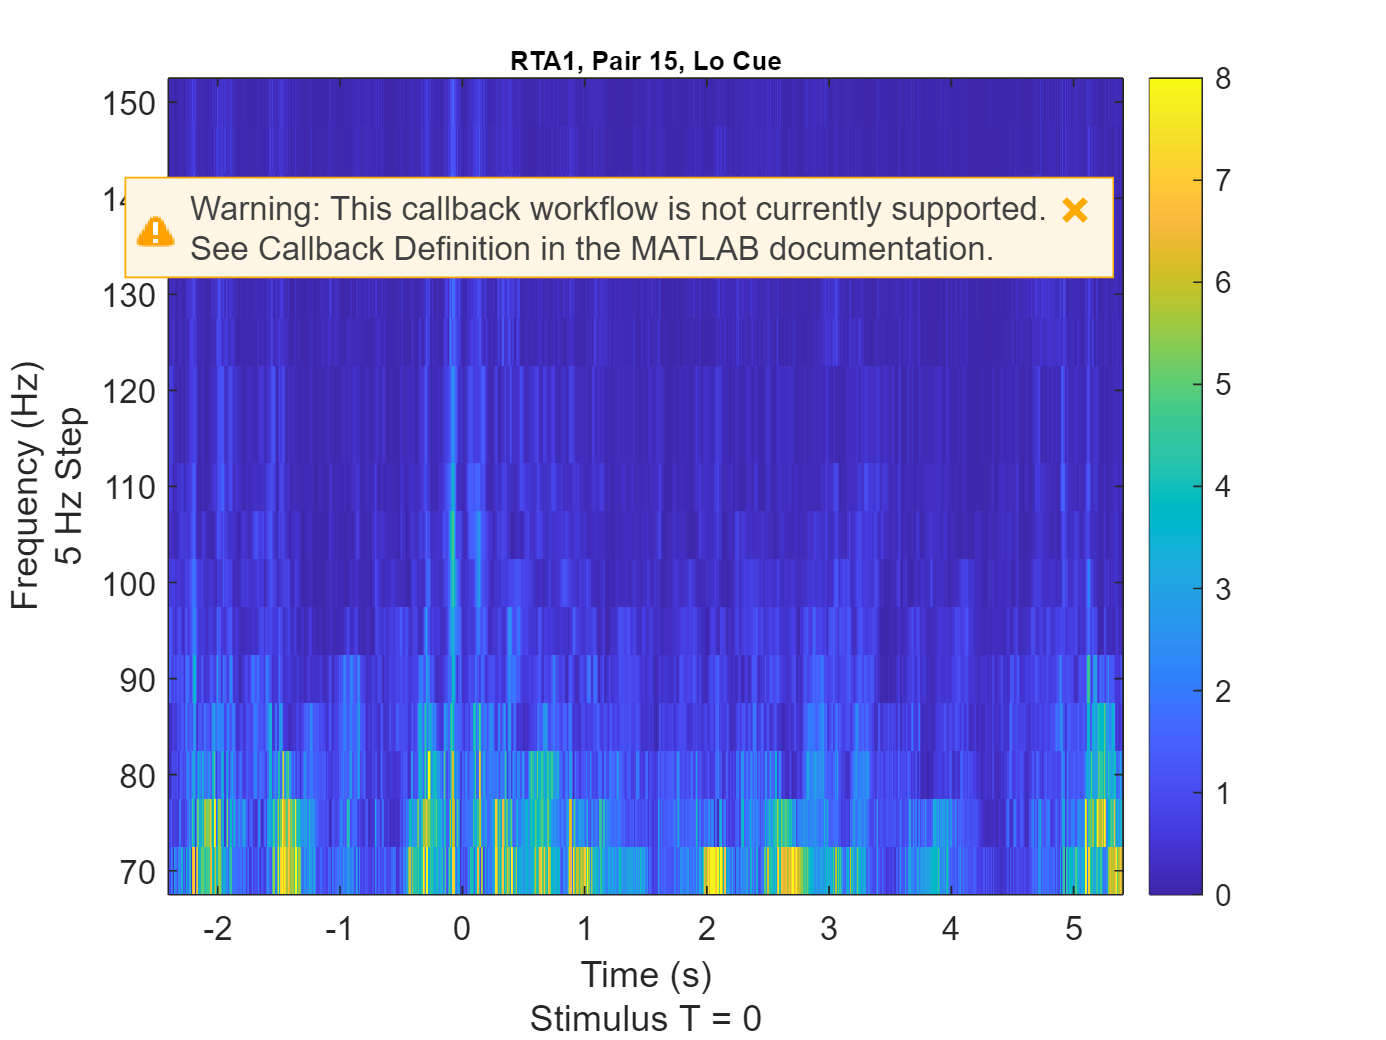


cfg.trials      = imgview_freq.trialinfo.highcue_indx == 1;
cfg.title = sprintf('%s Average Image Response, High Cue', cfg.channel);
ylabel({'Frequency (Hz)'; '5 Hz Step'})
xlabel({'Time (s)'; 'Stimulus T = 0'})

ft_singleplotTFR(cfg, imgview_freq)

the call to "ft_selectdata" took 1 seconds


the call to "ft_singleplotTFR" took 1 seconds


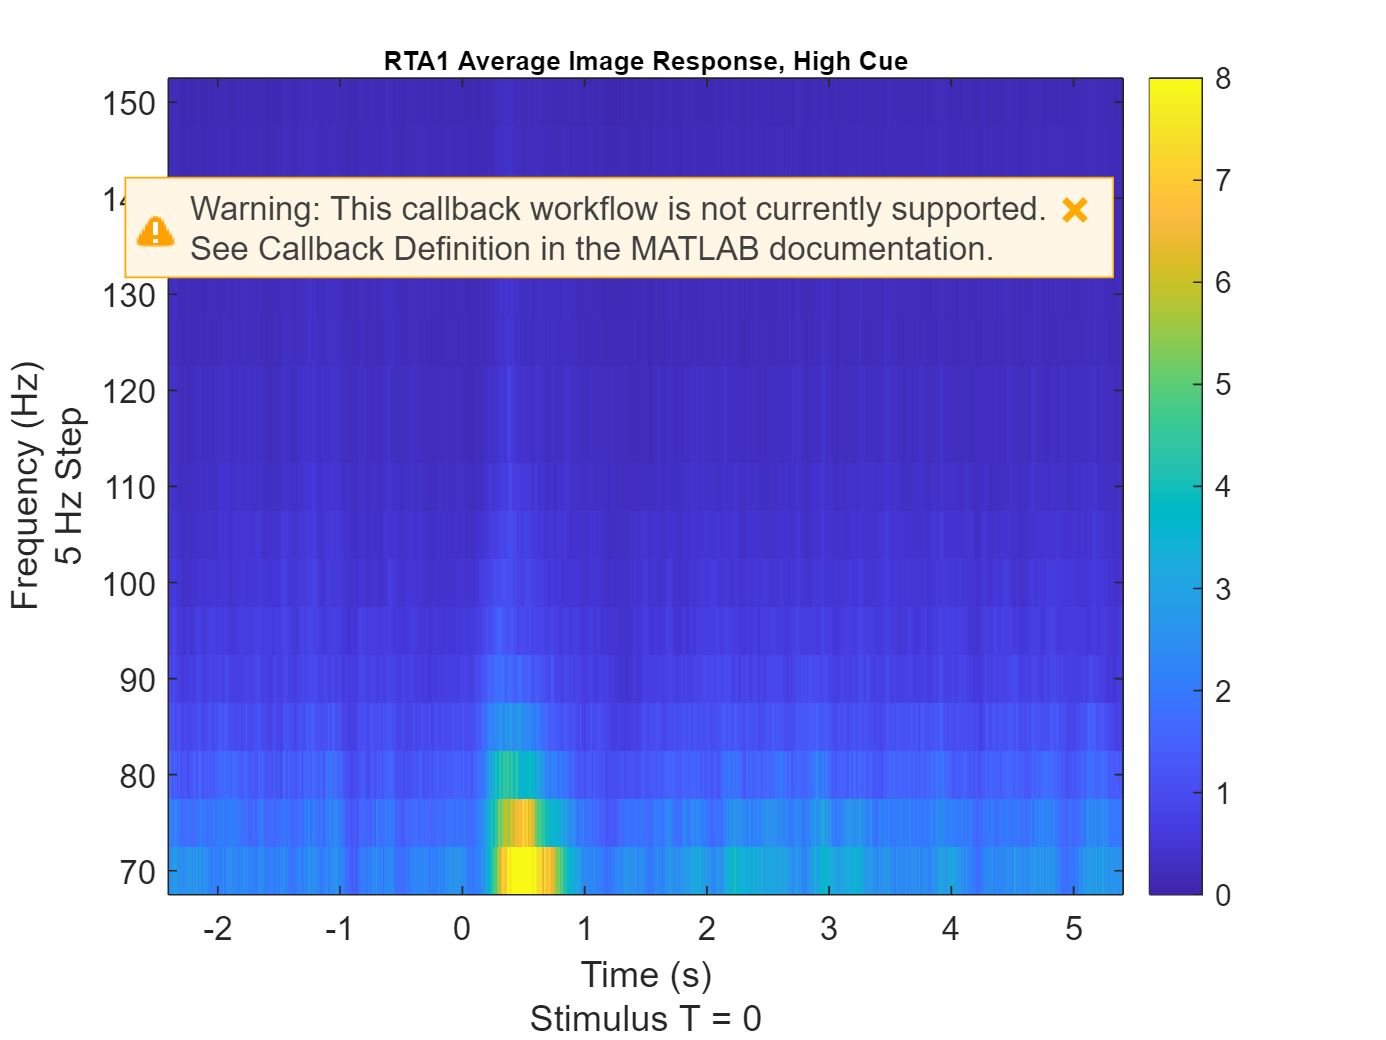


cfg.trials      = imgview_freq.trialinfo.highcue_indx == -1;
cfg.title = sprintf('%s Average Image Response, Low Cue', cfg.channel);
ylabel({'Frequency (Hz)'; '5 Hz Step'})
xlabel({'Time (s)'; 'Stimulus T = 0'})

ft_singleplotTFR(cfg, imgview_freq)

the call to "ft_selectdata" took 1 seconds


the call to "ft_singleplotTFR" took 1 seconds


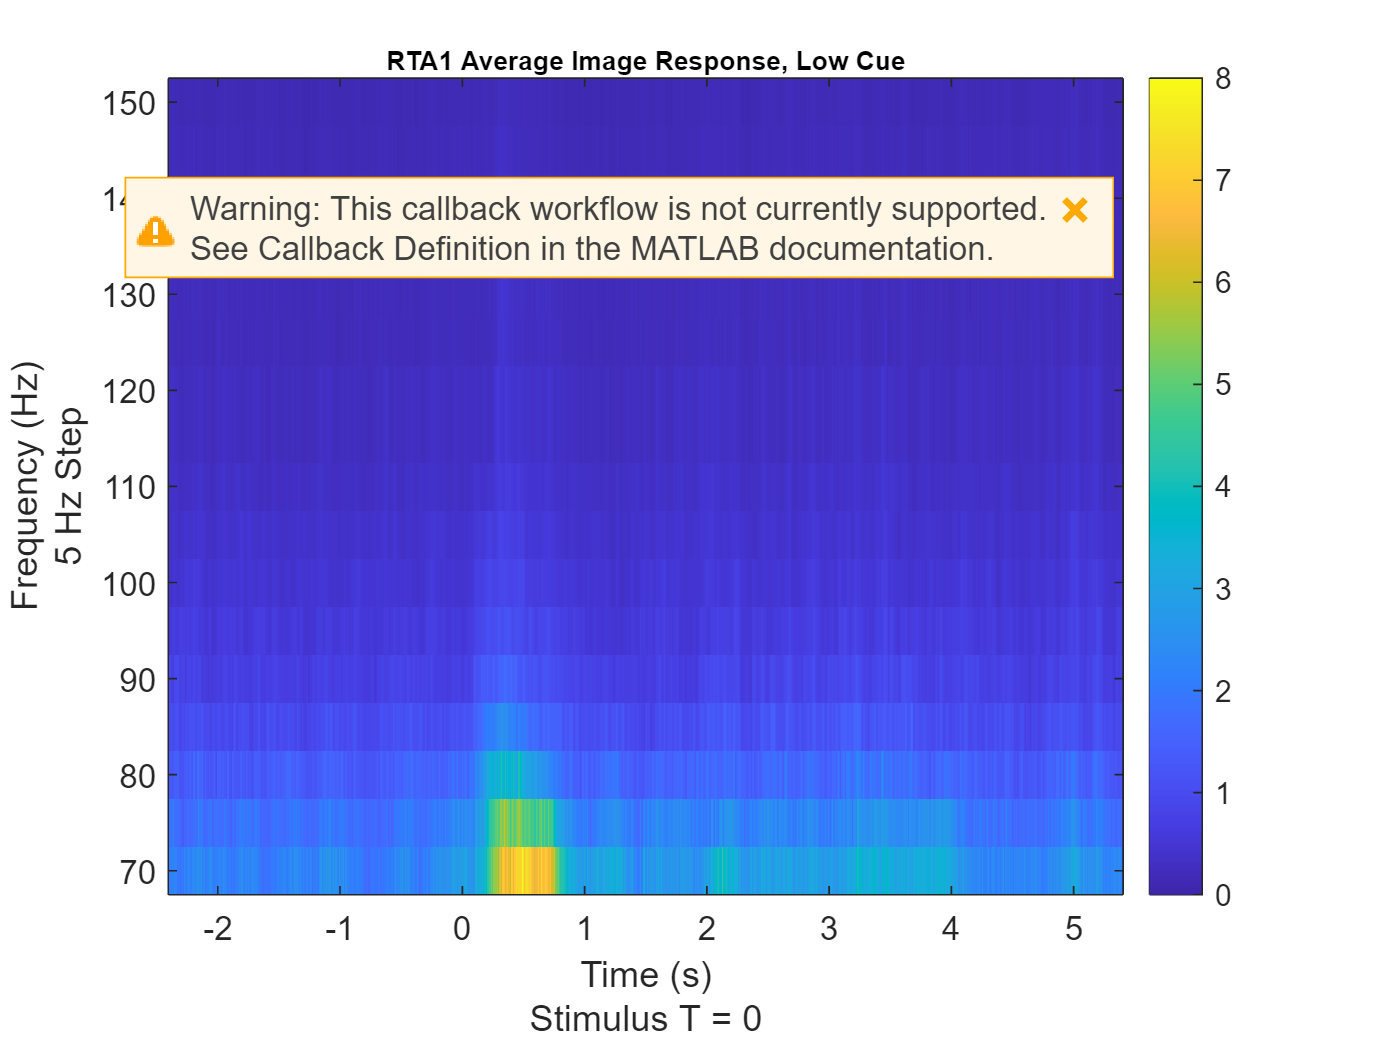


cfg.trials = pairs.hitrial(pairnum);
cfg.title = sprintf('%s, Pair %d, Hi Cue', cfg.channel, pairnum);
ylabel({'Frequency (Hz)'; '5 Hz Step'})
xlabel({'Time (s)'; 'Stimulus T = 0'})

ft_singleplotTFR(cfg, imgview_freq)

the call to "ft_selectdata" took 1 seconds


the call to "ft_singleplotTFR" took 1 seconds


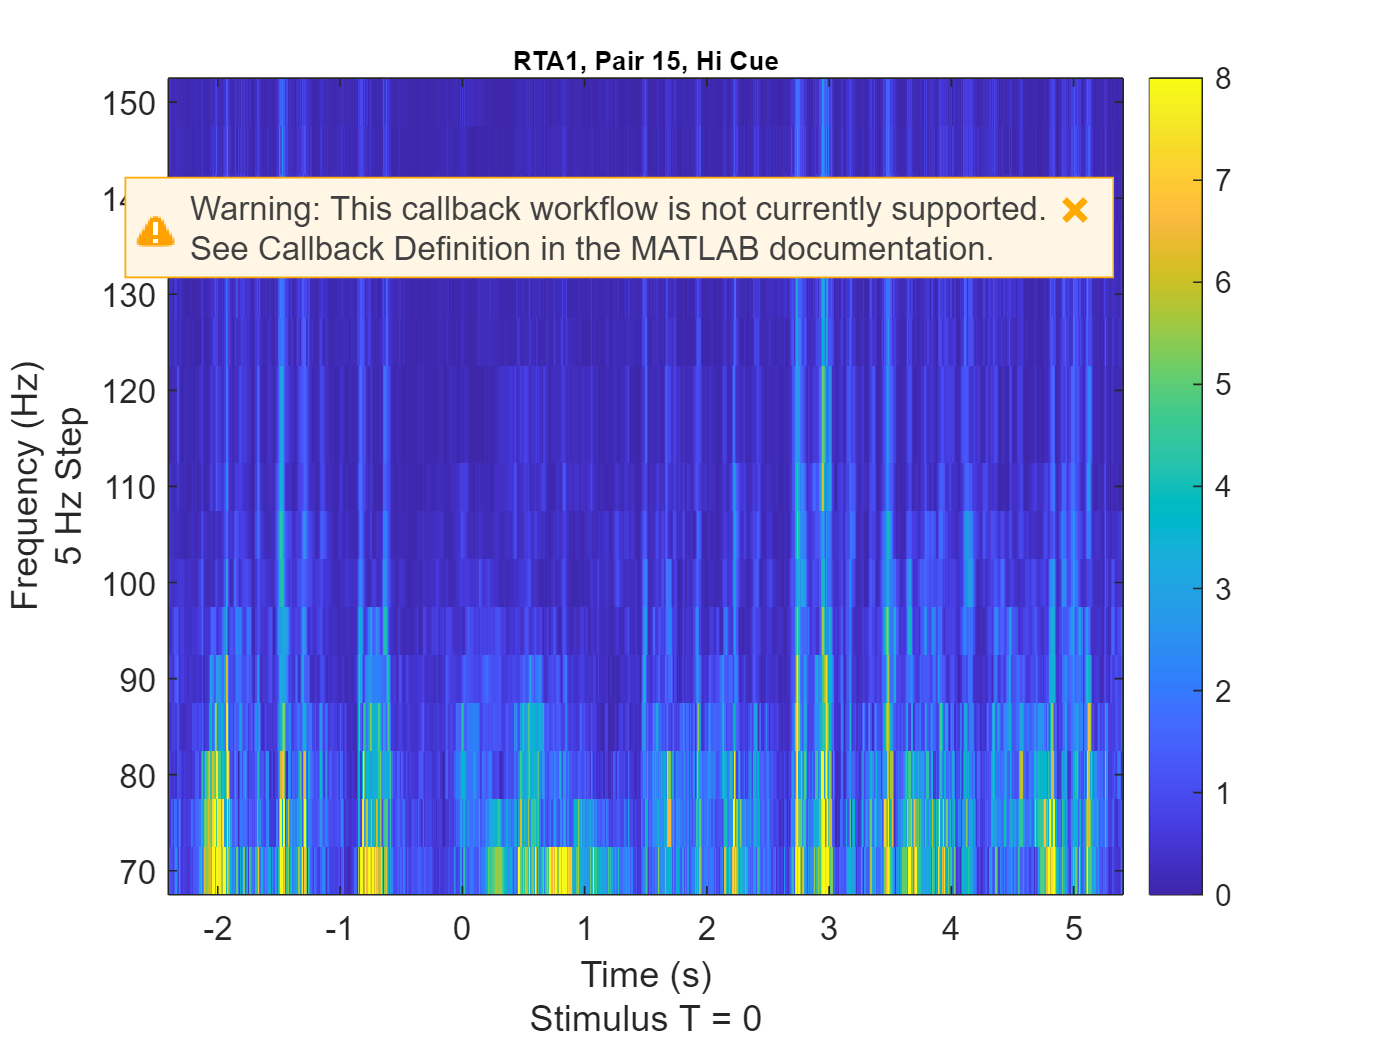


cfg.trials = pairs.lotrial(pairnum);
cfg.title = sprintf('%s, Pair %d, Lo Cue', cfg.channel, pairnum);
ylabel({'Frequency (Hz)'; '5 Hz Step'})
xlabel({'Time (s)'; 'Stimulus T = 0'})

the call to "ft_selectdata" took 1 seconds


the call to "ft_singleplotTFR" took 1 seconds


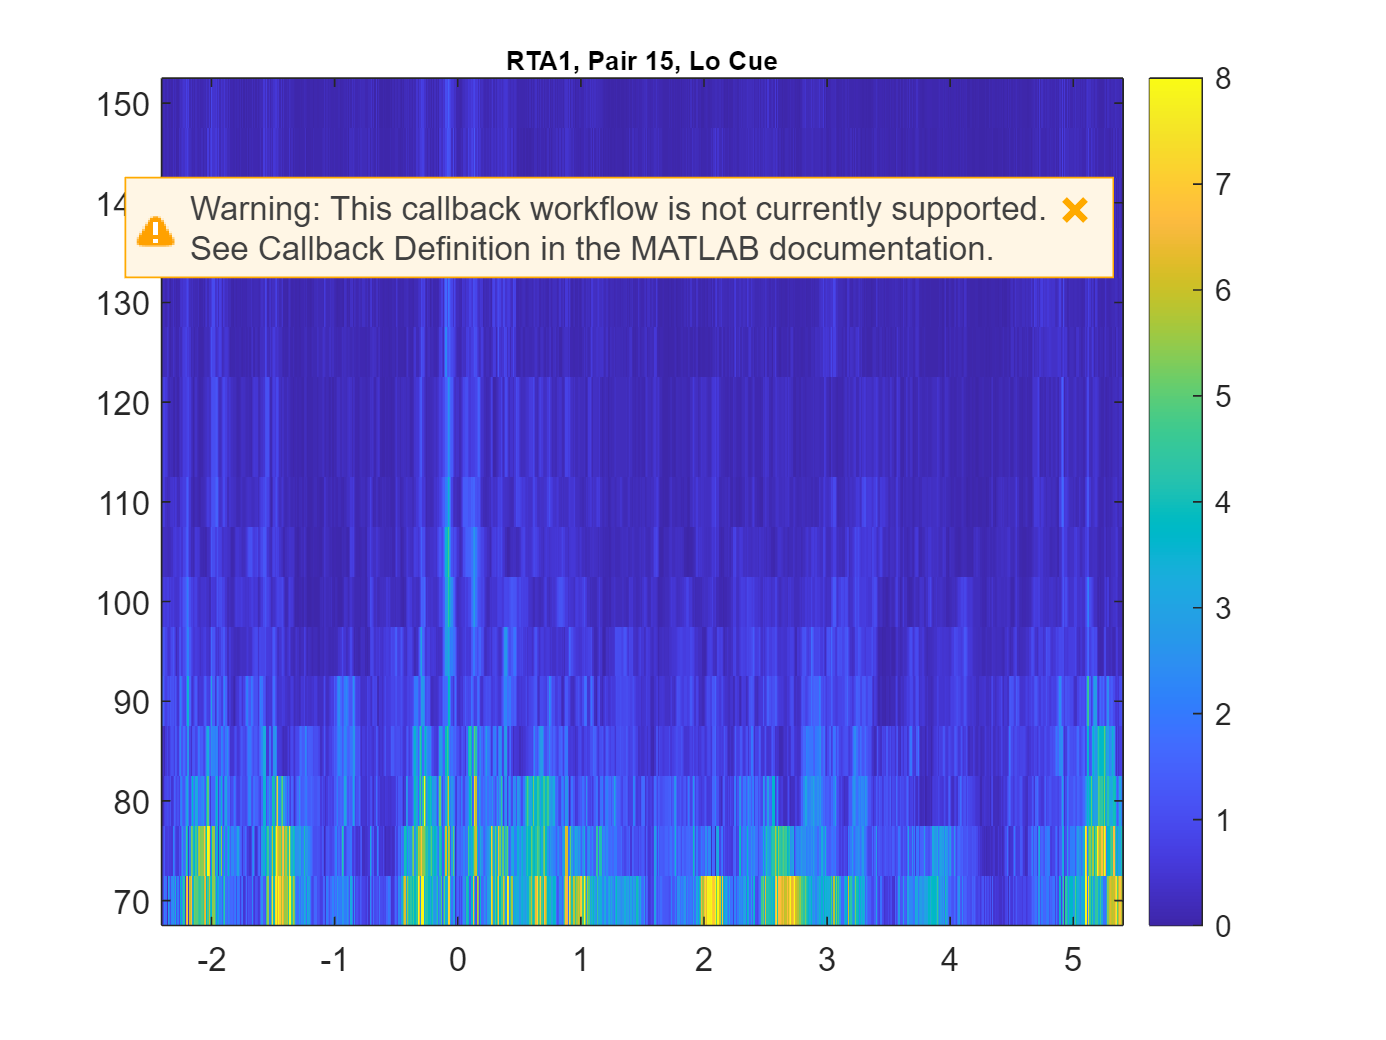

ft_singleplotTFR(cfg, imgview_freq)

We can compare ERPs for the same time period in each condition. The canonical ERP we anticipate with highly emotional image viewing is the P400, which occurs 400 ms after image onset. This should be strongest in the amygdala, but we see that it also seems to appear in most ROIs to a lesser extent as well. 

## Creating ERPs


cfg          = [];
cfg.keeptrials = 'yes';
cfg.channel = 'RTA1'

cfg = struct with fields:
    keeptrials: 'yes'
       channel: 'RTA1'


% imgview_ERP = ft_timelockanalysis(cfg, imgview);

cfg.trials = imgview_freq.trialinfo.highcue_indx == 1;
imgview_ERP_hicue   = ft_timelockanalysis(cfg,imgview);

the input is raw data with 141 channels and 64 trials
the call to "ft_selectdata" took 0 seconds
the call to "ft_timelockanalysis" took 0 seconds



cfg.trials = imgview_freq.trialinfo.highcue_indx == -1;
imgview_ERP_locue   = ft_timelockanalysis(cfg,imgview);

the input is raw data with 141 channels and 64 trials
the call to "ft_selectdata" took 0 seconds
the call to "ft_timelockanalysis" took 0 seconds


@Tor, since you mentioned that having a trial-specific baseline subtraction might be problematic, I've created two sets of variables to compare against one another in addition to the cue pair variables. In general, it seems that the baseline correction pulls the starting point closer to 0 and increase magnitude of signal. At the peak negative point of the P400 in the amygdala (channel RTA1), it seems to differentiate the two conditions more than the uncorrected version. We can discuss which way we'll proceed in the rest of the analysis. 

% baseline correction
cfg.baseline = [-0.5 -0.01];

imgview_ERP_hicue_bl = ft_timelockbaseline(cfg,imgview_ERP_hicue);

the input is timelock data with 141 channels and 16385 timebins
applying baseline correction on each individual trial
the call to "ft_timelockbaseline" took 2 seconds


imgview_ERP_locue_bl = ft_timelockbaseline(cfg,imgview_ERP_locue);

the input is timelock data with 141 channels and 16385 timebins
applying baseline correction on each individual trial
the call to "ft_timelockbaseline" took 2 seconds


cfg = [];
cfg.toi = imgview_ERP_locue_bl.time((2.5*hdr.Fs):(3.5*hdr.Fs))

cfg = struct with fields:
    toi: [-4.8828e-04 0 4.8828e-04 9.7656e-04 0.0015 0.0020 0.0024 0.0029 0.0034 0.0039 0.0044 0.0049 0.0054 0.0059 0.0063 0.0068 0.0073 0.0078 0.0083 0.0088 0.0093 0.0098 0.0103 0.0107 0.0112 0.0117 0.0122 0.0127 0.0132 0.0137 0.0142 0.0146 0.0151 … ]


cfg.channel = 'RTA1'

cfg = struct with fields:
        toi: [-4.8828e-04 0 4.8828e-04 9.7656e-04 0.0015 0.0020 0.0024 0.0029 0.0034 0.0039 0.0044 0.0049 0.0054 0.0059 0.0063 0.0068 0.0073 0.0078 0.0083 0.0088 0.0093 0.0098 0.0103 0.0107 0.0112 0.0117 0.0122 0.0127 0.0132 0.0137 0.0142 0.0146 … ]
    channel: 'RTA1'


cfg.trials = 15;
imgview_ERP_hicue_trial = ft_selectdata(cfg, imgview_ERP_hicue_bl)

the call to "ft_selectdata" took 0 seconds


imgview_ERP_hicue_trial = struct with fields:
          time: [-2.5000 -2.4995 -2.4990 -2.4985 -2.4980 -2.4976 -2.4971 -2.4966 -2.4961 -2.4956 -2.4951 -2.4946 -2.4941 -2.4937 -2.4932 -2.4927 -2.4922 -2.4917 -2.4912 -2.4907 -2.4902 -2.4897 -2.4893 -2.4888 -2.4883 -2.4878 -2.4873 -2.4868 -2.4863 … ]
         label: {'RTA1'}
    sampleinfo: [1821771 1838155]
         trial: [1×1×16385 double]
     trialinfo: [1×54 table]
           cfg: [1×1 struct]
        dimord: 'rpt_chan_time'


imgview_ERP_locue_trial = ft_selectdata(cfg, imgview_ERP_locue_bl);

the call to "ft_selectdata" took 0 seconds


[h,p,ci,stats] = ttest(imgview_ERP_hicue_bl.avg, imgview_ERP_locue_bl.avg)

Unrecognized field name "avg".


cfg = [];
cfg.channel = 'RTA1';

cfg.title = (sprintf('%s Average ERP at Stimulus Onset', cfg.channel))

cfg = struct with fields:
    channel: 'RTA1'
      title: 'RTA1 Average ERP at Stimulus Onset'


legend('High Cue', 'Low Cue')

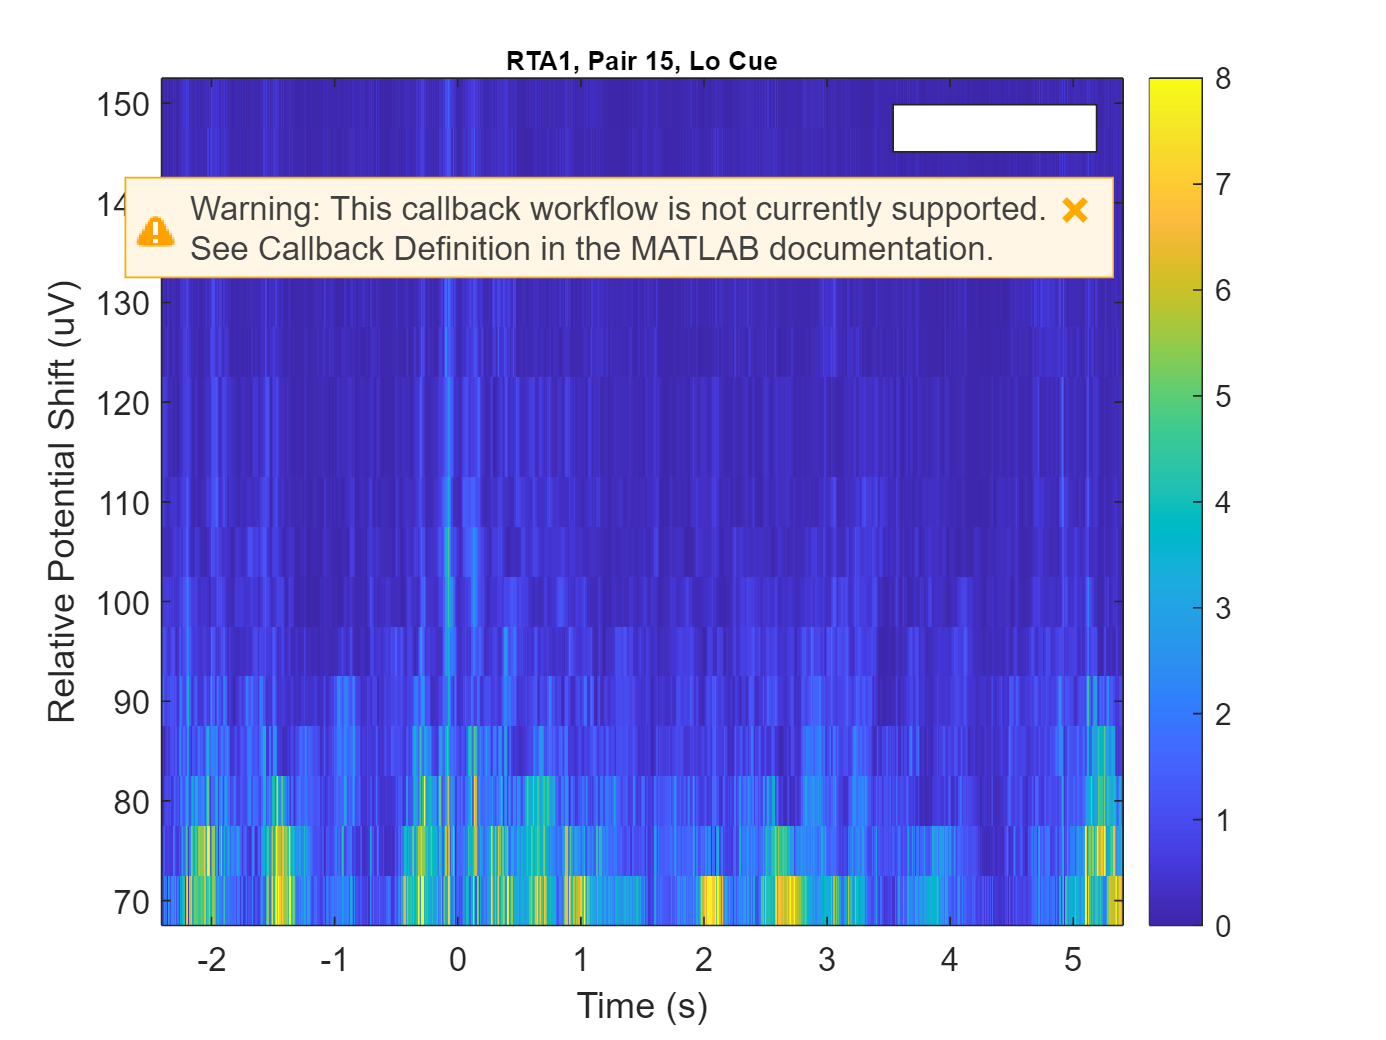

xlabel('Time (s)');
ylabel('Relative Potential Shift (uV)');

the call to "ft_selectdata" took 0 seconds
the call to "ft_singleplotER" took 0 seconds


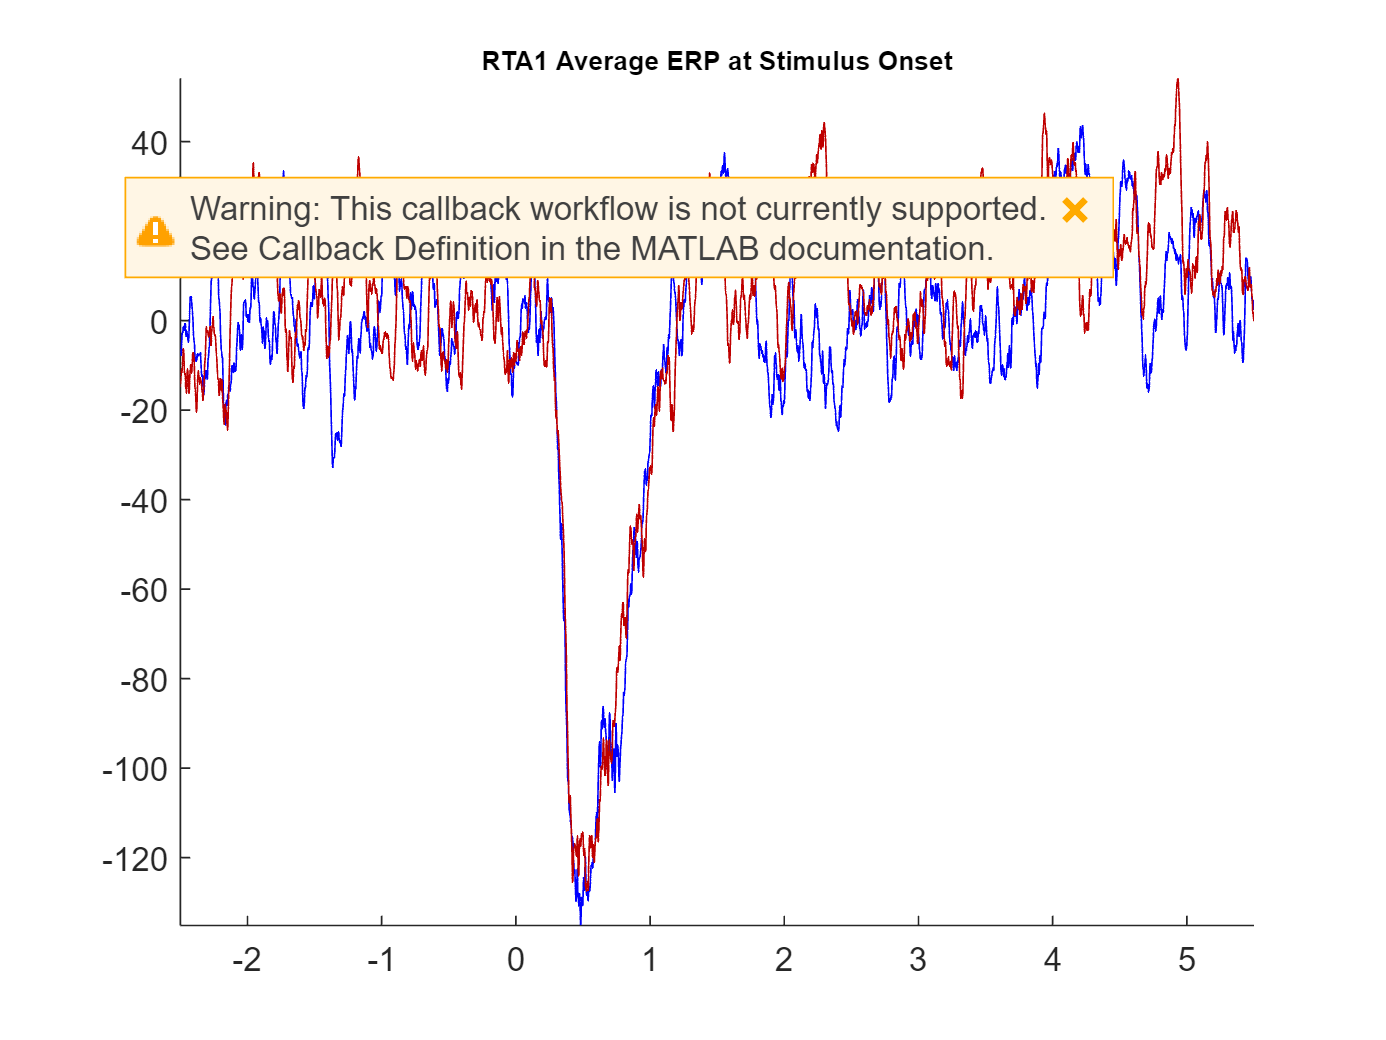

ft_singleplotER(cfg, imgview_ERP_hicue, imgview_ERP_locue);

cfg.title= sprintf('%s Baseline Shifted ERP at Stimulus Onset', cfg.channel)

cfg = struct with fields:
    channel: 'RTA1'
      title: 'RTA1 Baseline Shifted ERP at Stimulus Onset'


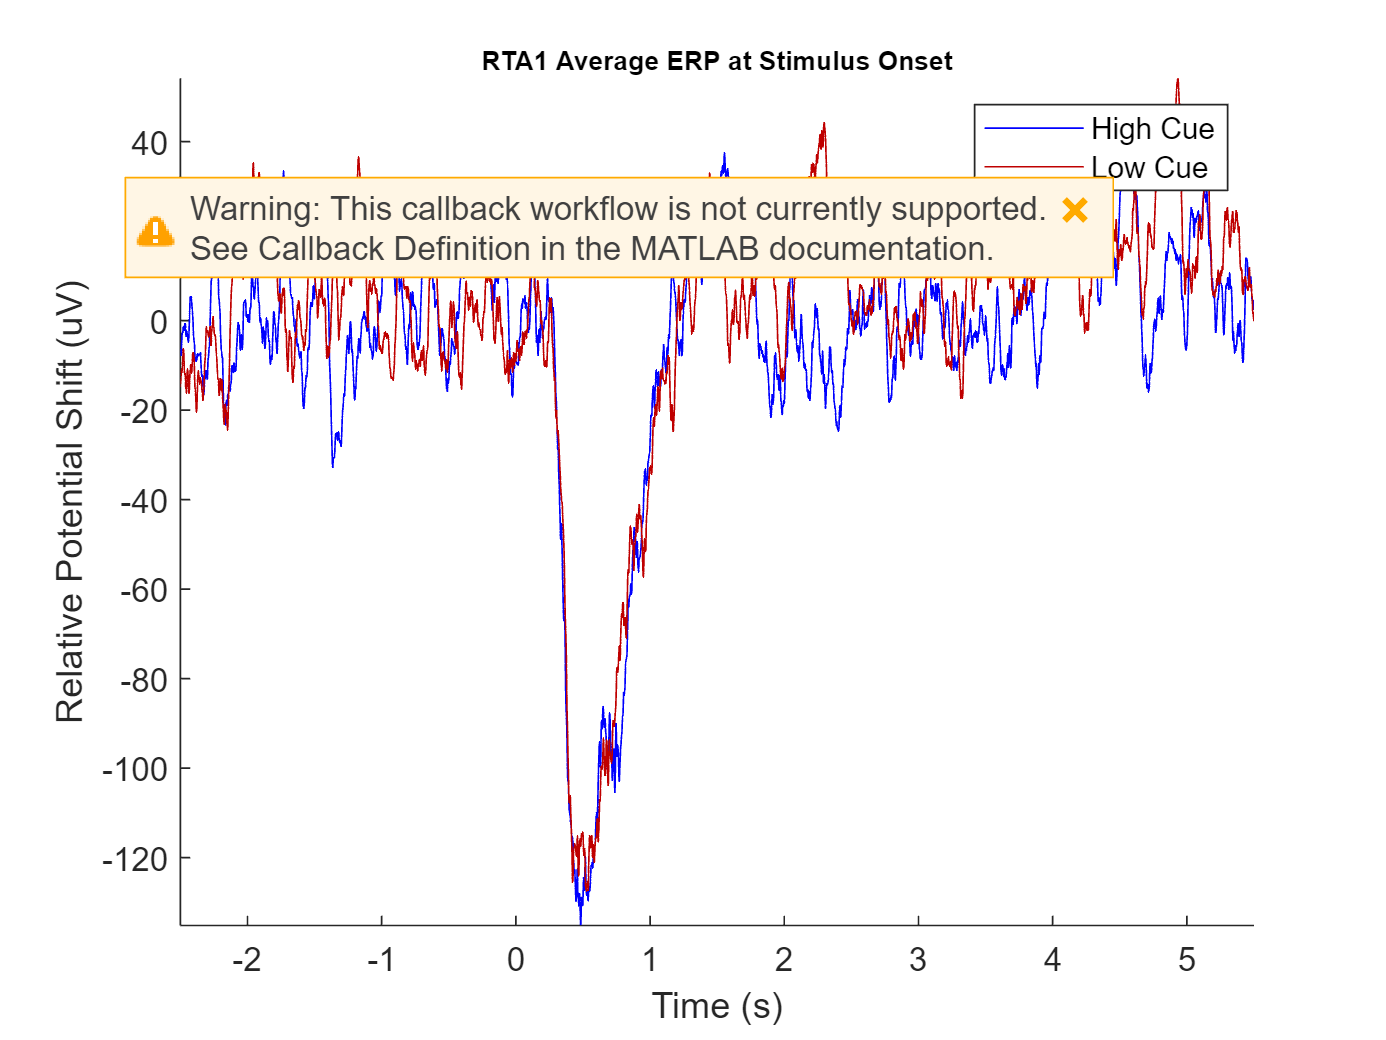

legend('High Cue', 'Low Cue')
xlabel('Time (s)');
ylabel('Relative Potential Shift (uV)');

the call to "ft_selectdata" took 0 seconds
the call to "ft_singleplotER" took 0 seconds


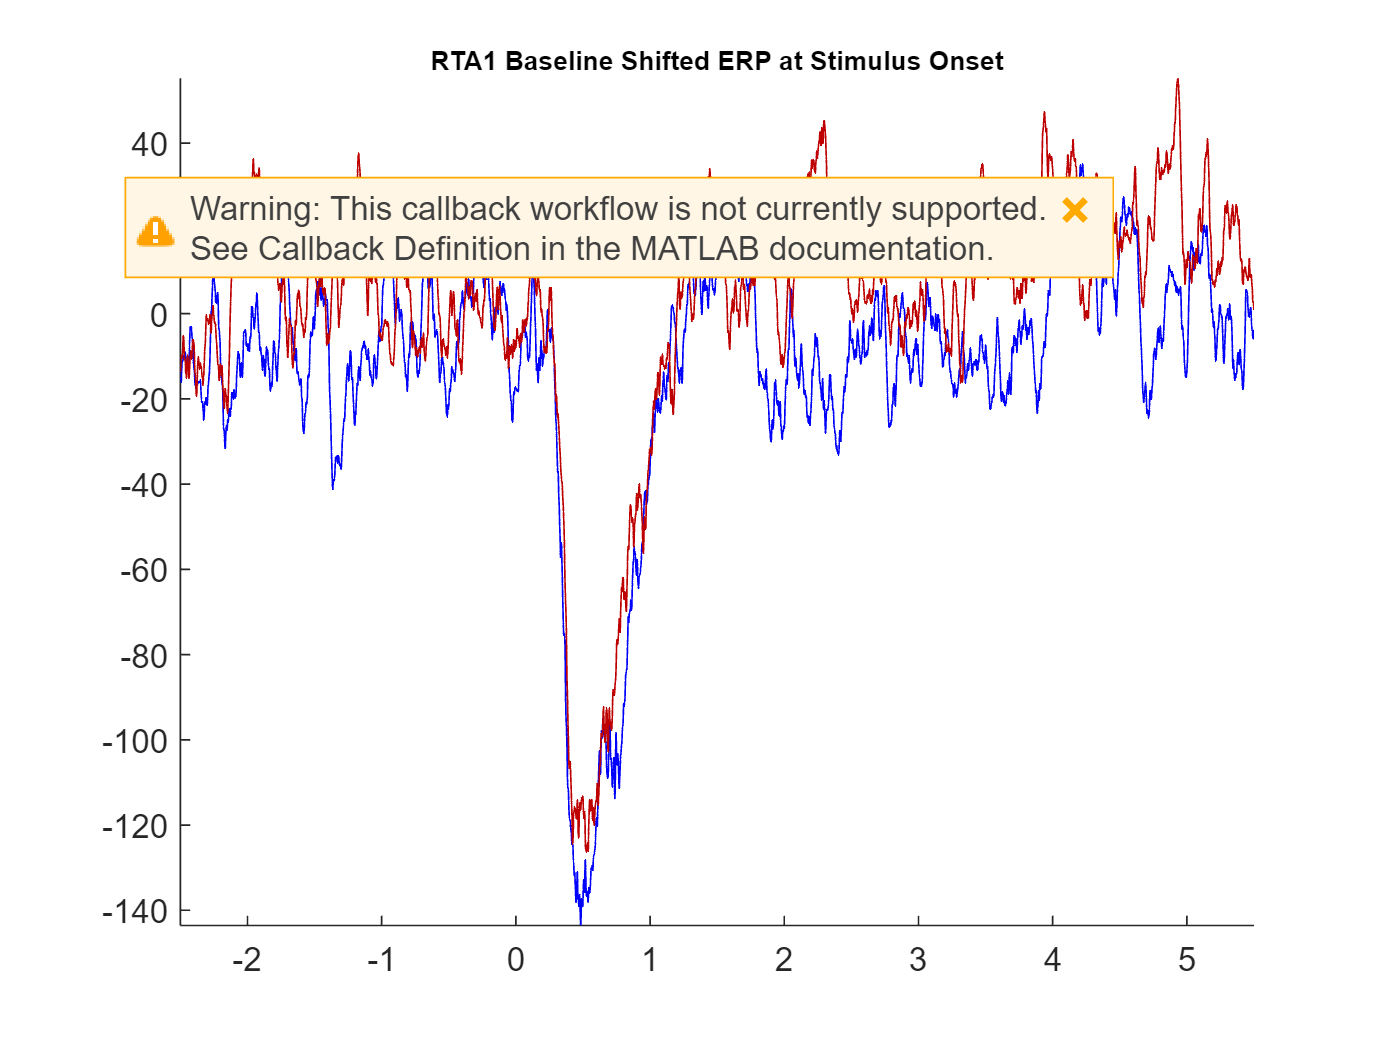

ft_singleplotER(cfg, imgview_ERP_hicue_bl, imgview_ERP_locue_bl);

cfg.trials = imgview_freq.trialinfo.highcue_indx == 1;

imgview_freq_hicue = ft_selectdata(cfg, imgview_freq);

the call to "ft_selectdata" took 0 seconds


cfg.trials = imgview_freq.trialinfo.highcue_indx == -1;
imgview_freq_locue = ft_selectdata(cfg, imgview_freq);

the call to "ft_selectdata" took 0 seconds



cfg = [];
cfg.channel = 'RTA1';
cfg.title = sprintf('%s Baseline Shifted ERP at Stimulus Onset', cfg.channel)

cfg = struct with fields:
    channel: 'RTA1'
      title: 'RTA1 Baseline Shifted ERP at Stimulus Onset'


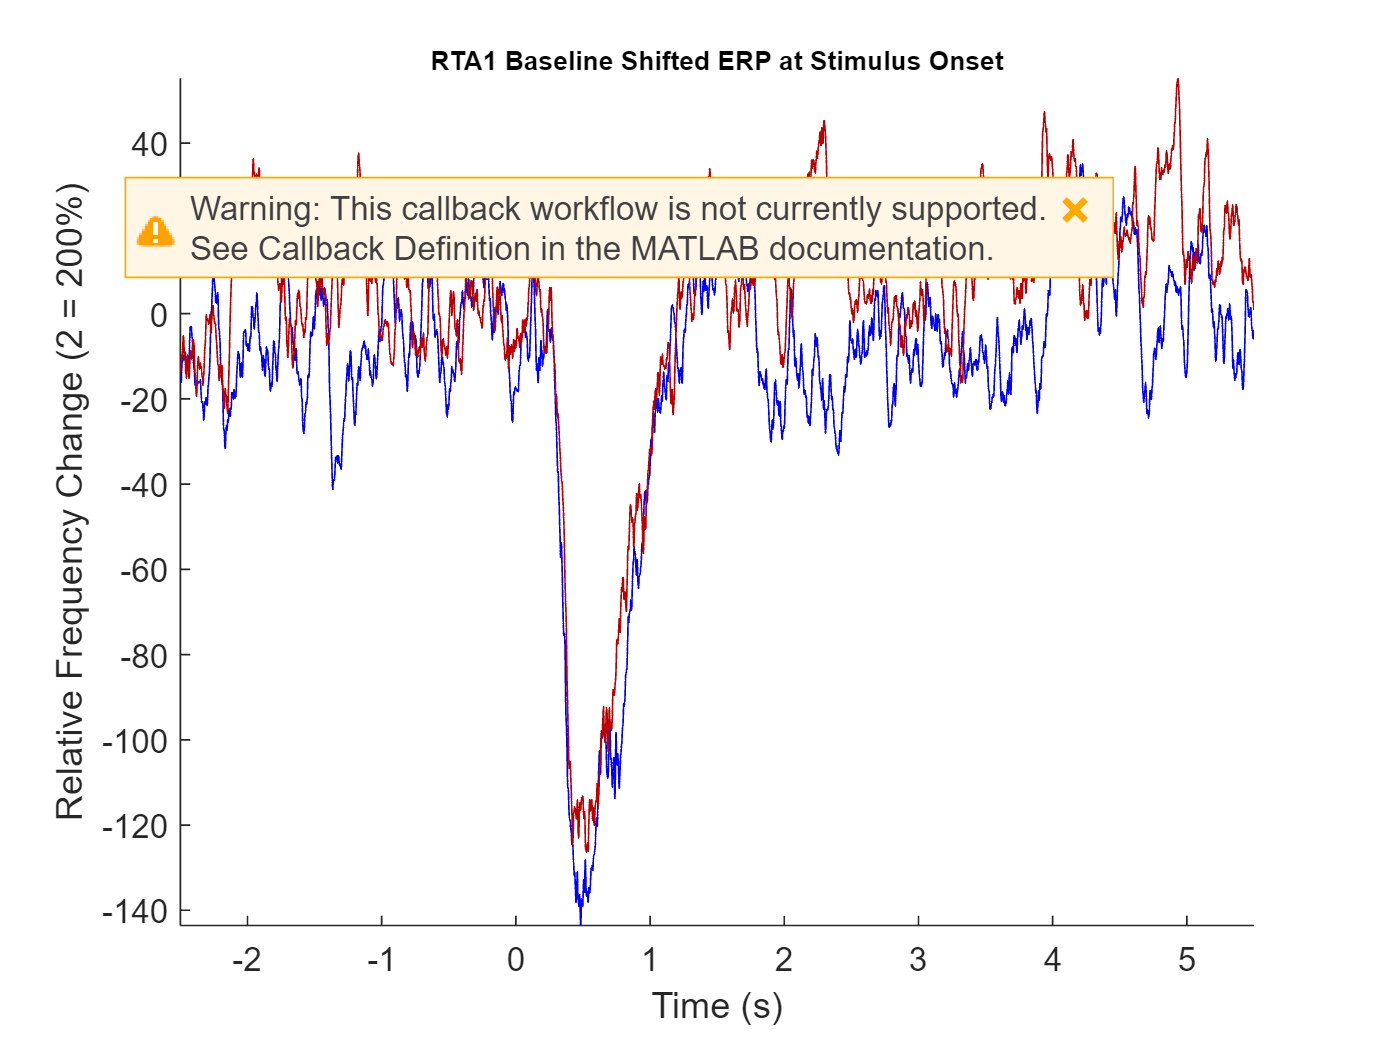

ylabel('Relative Frequency Change (2 = 200%)')
xlabel('Time (s)')

the call to "ft_selectdata" took 0 seconds
the call to "ft_singleplotER" took 0 seconds


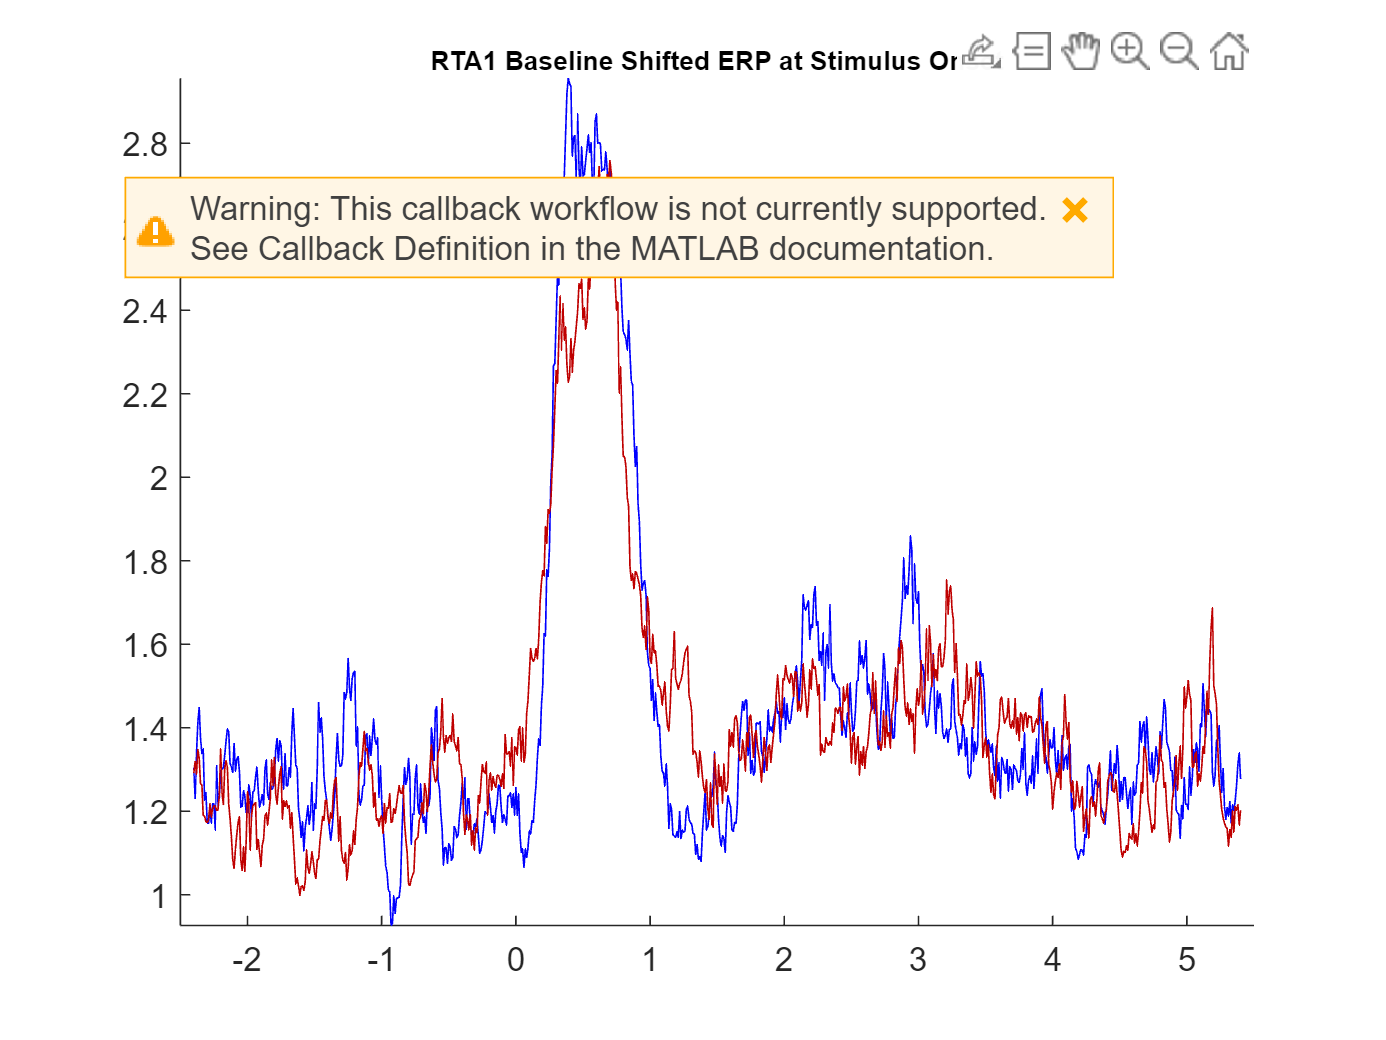

ft_singleplotER(cfg, imgview_freq_hicue, imgview_freq_locue);

% ft_singleplotER(cfg, imgview_freq)

